clear all
clc

% This file considers the velocity control problem 
% to guarantee that the rotor and the unknown load rotate at steady state at a given angular velocity
% Student Name: Giuditta Sigona
% Created on 21/03/2022
% Last version xx/yy/zz

% matlab colors
NMatlabRed      = [0.8500   0.3250   0.0980];
NMatlabYellow   = [0.929    0.694    0.125 ];
NMatlabBlue     = [0        0.4470   0.7410];  
NMatlabViolet   = [0.4940   0.1840   0.5560];
NMatlabGreen    = [0.4660   0.6740   0.1880];
NMatlabCyan     = [0.3010   0.7450   0.9330];
NMatlabBordeaux = [0.6350   0.0780   0.1840]; 

s = tf('s');
om = logspace(-2,5,1000);
t = 0:0.001:10;

% Parameters (MATLAB)
R = 2.0;                % Ohms
L = 0.5;                % Henrys
K = 0.1;               % torque constant
K = 0.1;               % back emf constant
b = 0.2;               % Nms
J = 0.02;               % kg.m^2/s^2

Td = -0.2;   % disturbance T_load torque

P1 = tf(K,[L R]);            % armature
P2 = tf(1,[J b]);            % eqn of motion

sys = feedback(P1*P2,K);   % close back emf loop
% stepplot(sys(1));
disturbed_sys = Td*feedback(P2,P1*K) % Disturbance (load torque) transfer function

disturbed_sys =
 
        -0.1 s - 0.4
  ------------------------
  0.01 s^2 + 0.14 s + 0.41
 
Continuous-time transfer function.




Cont = pidtune(sys, 'pid')  % PID Controller 

Cont =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 8.62, Ki = 36.5, Kd = 0.509
 
Continuous-time PID controller in parallel form.



SF0 = loopsens(sys, Cont);  % all the sensitivities functions

P_DCont = minreal(disturbed_sys*SF0.Si);  % Disturbo con il controllo

4 states removed.


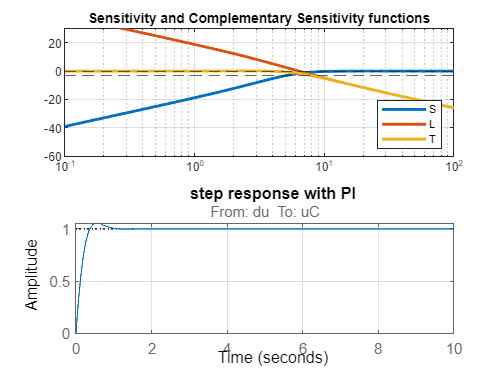


figure(1)
subplot(211)
[magS0,phaseS0]=bode(SF0.Si,om);
[magT0,phaseT0]=bode(SF0.Ti,om);
[magL0,phaseL0]=bode(SF0.Li,om);
[magC0,phaseC0]=bode(Cont,om);
Plot1 = semilogx(om,20*log10(magS0(1,:)),...
    om,20*log10(magL0(1,:)),...
    om,20*log10(magT0(1,:))); grid
set(Plot1,'LineWidth',2)
yline(0,'--')
yline(-3, '--')
legend('S','L','T','Location','SouthEast');
title('Sensitivity and Complementary Sensitivity functions')
ylim([-60,30])
xlim([1.e-1,1.e+2])

figure(1)
subplot(212)
step(SF0.Ti,t); grid % Step response of the closed loop system with PI controller
title('step response with PI');


% ----------  Minimizing the weighted sensitivity function -----------
% choose a weight function on the basis of the obtained sensitivity function 
% the optimal controller which minimize the min || . || is such that
% | wBS1(jω) S(jω)| = constant 

% A1 = 0.02;    % low frequency behavior of specs of |S| (the value associated to S(0) )
%                % when ω=0 --> -34dB = 0.05
% wBS1 = 3;   % is the lower bound on B3S  so it must be <3.37
% M1 = 1.4;    % = 2.6 db is the upper bound for |S(jω)|, generally belongs to [1.4, 2]
%               % peak of S
% wS1 = (s/M1 +wBS1)/(s+wBS1*A1) %should be A.S. and M.P.

A1 = 7*10^-3;    % low frequency behavior of specs of |S| (the value associated to S(0) )
               % when ω=0 --> -43dB
wBS1 = 4;   % is the lower bound on B3S  so it must be <3.37
M1 = 1.1;    %  is the upper bound for |S(jω)|, generally belongs to [1.4, 2]
              % peak of S
wS1 = (s/M1 +wBS1)/(s+wBS1*A1) %should be A.S. and M.P.

wS1 =
 
     s + 4.4
  --------------
  1.1 s + 0.0308
 
Continuous-time transfer function.




% wBT1 = ; % upper bound 
% Mt1 = ; %peak of T(jw)
% At = ;
% wT = (s+wBT1/Mt1)/(At*s + wBT1); 

%Controller design through mixsyn 
[C1,CL1,GAM1] = mixsyn(sys,wS1,[]);     %controller with only Ws
GAM1

GAM1 = 0.9156

SF1 = loopsens(sys,C1);
tf(C1)

ans =
 
   3.636e05 s^2 + 5.09e06 s + 1.491e07
  --------------------------------------
  s^3 + 1357 s^2 + 8.376e05 s + 2.345e04
 
Continuous-time transfer function.




%add a constant weight Wu
% wu = 0.3;  % = wT or a constant
wu = 0.01;  % = wT or a constant
[C2,CL2,GAM2] = mixsyn(sys,wS1,wu,[]);       %controller with Ws and Wu
GAM2    %constant gamma

GAM2 = 0.9688

SF1a = loopsens(sys,C2);
tf(C2)

ans =
 
  1.792e04 s^2 + 2.508e05 s + 7.346e05
  ------------------------------------
  s^3 + 610.5 s^2 + 4.367e04 s + 1222
 
Continuous-time transfer function.



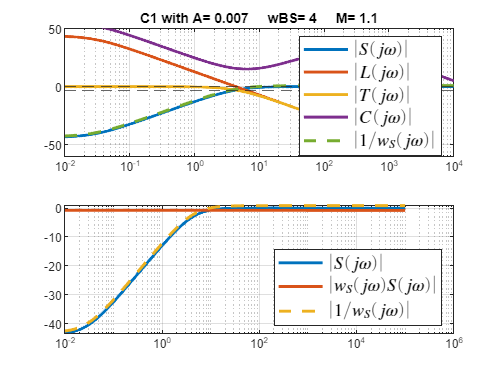


figure(2)
subplot(211)
[magwS2,phasewS1]=bode(wS1,om);          % weight
[magS2,phaseS1]=bode(SF1.Si,om);
[magT2,phaseT1]=bode(SF1.Ti,om);
[magL2,phaseL1]=bode(SF1.Li,om);
[magC2,phaseC1]=bode(C2,om);             % optimal controller
[magwSS2,phasewSS1]=bode(wS1*SF1.Si,om); % weighted sensitivity
Plot3 = semilogx(om,20*log10(magS2(1,:)),...
    om,20*log10(magL2(1,:)),om,20*log10(magT2(1,:)),...
    om,20*log10(magC2(1,:)),om,-20*log10(magwS2(1,:)),'--'); grid
set(Plot3,'LineWidth',2)
yline(0,'--')
yline(-3,'--')
legC = legend('$|S(j\omega)|$','$|L(j\omega)|$','$|T(j\omega)|$','$|C(j\omega)|$','$|1/w_S(j\omega)|$',...
    'Interpreter','latex','Location','SouthEast');
set(legC,'FontSize',12)
title(['C1 with A= ' num2str(A1) '     wBS= ' num2str(wBS1) ...
           '     M= ' num2str(M1)]);
ylim([-60,50])
xlim([1.e-2,1.e+4])

figure(2)
subplot(212)
Plot4 = semilogx(om,20*log10(magS2(1,:)),om,20*log10(magwSS2(1,:)),...
                 om,-20*log10(magwS2(1,:)),'--'); grid
set(Plot4,'LineWidth',2)
leg4 = legend('$|S(j\omega)|$','$|w_S(j\omega)S(j\omega)|$','$|1/w_S(j\omega)|$','Location','SouthEast',...
        'Interpreter', 'latex');
set(leg4,'FontSize',12)

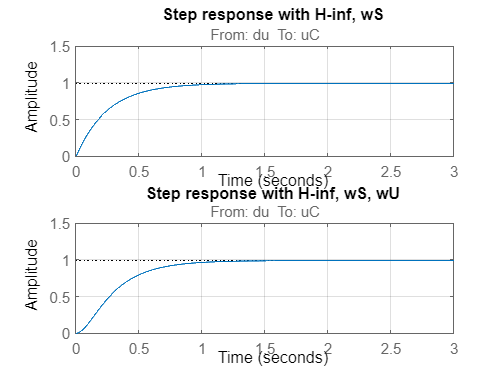


figure(3)
subplot(211)
step(SF1.Ti,t); grid
title('Step response with H-inf, wS')
ylim([0,1.5])
xlim([0,3])

%in the absence of particular limiting situations, the optimal controller
%is such that | wBS1(jω) S(jω)| = constant 
subplot(212)
step(SF1a.Ti,t); grid
title('Step response with H-inf, wS, wU')
ylim([0,1.5])
xlim([0,3])

%----------------------------------------------------------------


